% The code might take several minutes to complete the bootstrap 
% (if you reduce the number of simulations to 100 it will run much faster)

% Load the data
data = readtable('data_ps3.xlsx', 'Sheet', 1); % First sheet of the file

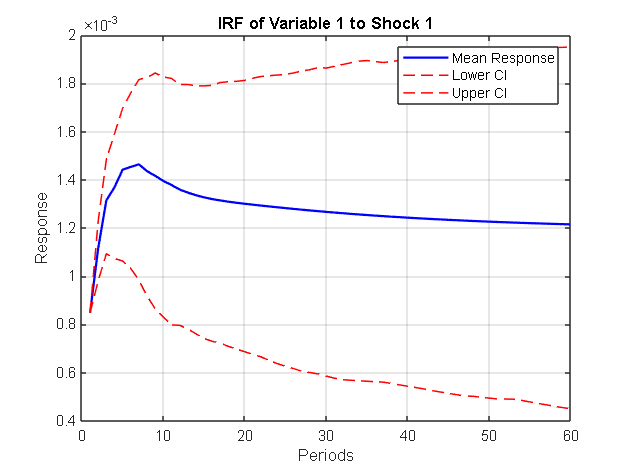

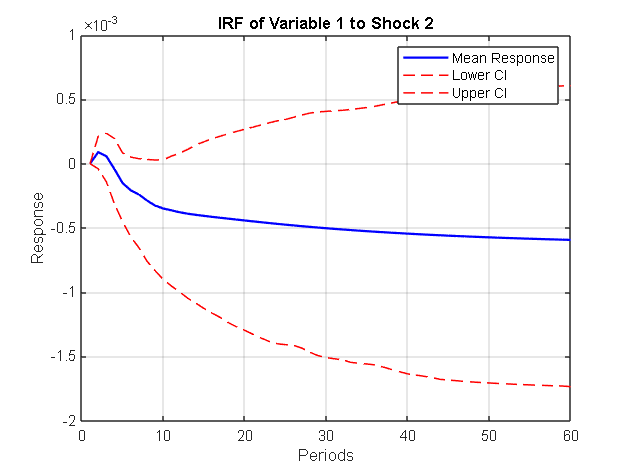

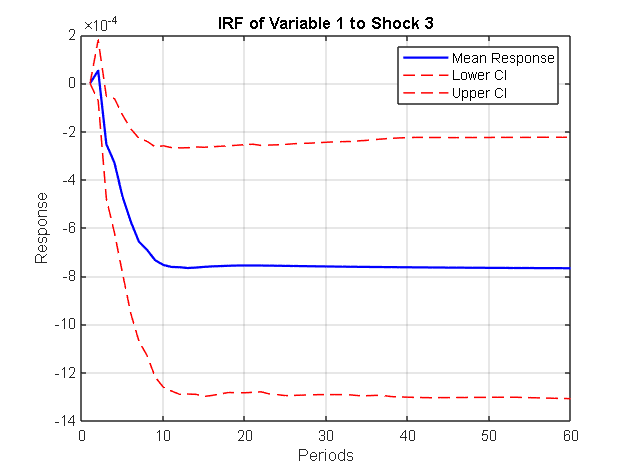

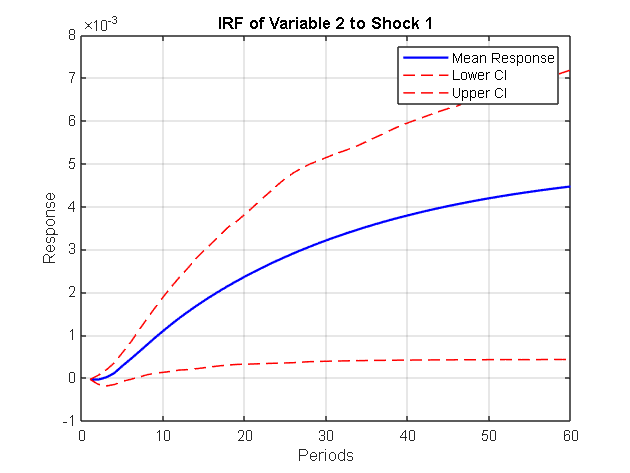

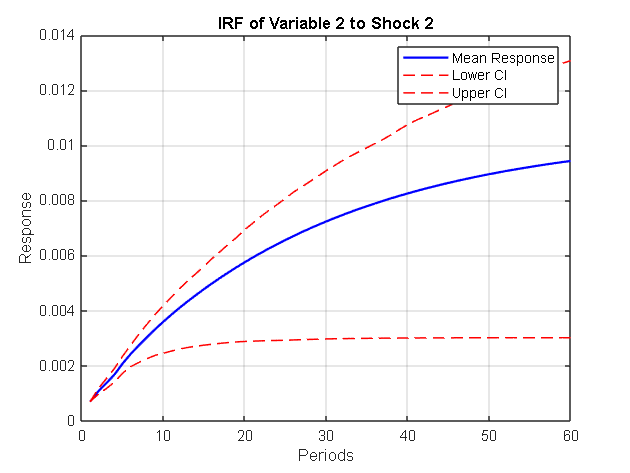

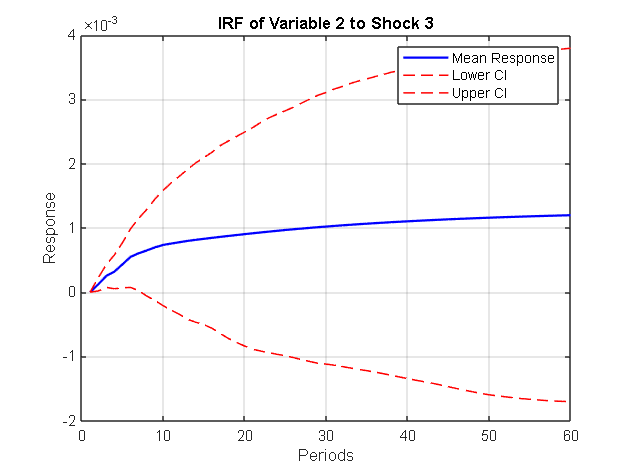

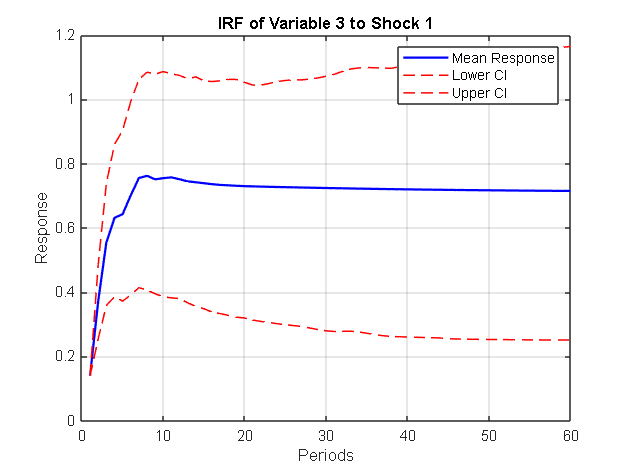

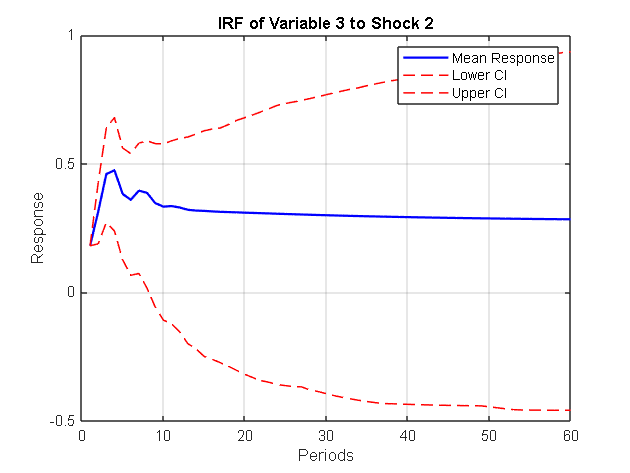

GDP = diff(log(table2array(data(:, 2)))); % Log-difference of real GDP
Prices = diff(log(table2array(data(:, 3)))); % Log-difference of price deflator
FFR = diff(table2array(data(:, 4))); % First difference of federal funds rate

% Set the variables for the VAR model
Y = [GDP, Prices, FFR]; % Matrix of variables
numVars = size(Y, 2); % Number of variables in the model
numLags = 4; % Number of lags for the VAR

% Step 1: Estimate the VAR(4) model
Mdl = varm(numVars, numLags); % Specify the VAR(4) model
EstMdl = estimate(Mdl, Y); % Estimate the VAR model

% Step 2: Compute residuals and covariance matrix
residuals = infer(EstMdl, Y); % Reduced-form residuals
cov_resid = cov(residuals); % Covariance matrix of the residuals

% Step 3: Cholesky decomposition for structural identification
A0_inv = chol(cov_resid, 'lower'); % Lower triangular matrix (Cholesky decomposition)

% Step 4: Compute impulse response functions (IRFs)
impulse_horizon = 60; % Set the horizon for IRFs
IRFs = zeros(numVars, numVars, impulse_horizon); % Initialize IRFs storage

% Compute the IRFs iteratively
for h = 1:impulse_horizon
    response = A0_inv; % Initial response to shocks
    for lag = 1:min(h-1, numLags)
        response = response + EstMdl.AR{lag} * IRFs(:, :, h-lag); % Add lagged responses
    end
    IRFs(:, :, h) = response; % Store the response for horizon h
end

% Step 5: Perform bootstrap for confidence intervals
n_boot = 1000; % Number of bootstrap iterations
conf_level = 0.95; % Confidence level for intervals
lower_bound = (1 - conf_level) / 2; % Lower quantile
upper_bound = 1 - lower_bound; % Upper quantile

IRF_boot = zeros(numVars, numVars, impulse_horizon, n_boot); % Storage for bootstrap IRFs

rng(123); % Set random seed for reproducibility
for b = 1:n_boot
    % Resample residuals with replacement
    boot_residuals = residuals(randi(size(residuals, 1), size(residuals, 1), 1), :);
    
    % Generate a new time series with bootstrap residuals
    boot_data = zeros(size(Y));
    boot_data(1:numLags, :) = Y(1:numLags, :); % Use original data for initial lags
    for t = (numLags+1):size(Y, 1)
        % Forecast the next value based on VAR(4)
        forecast = zeros(1, numVars);
        for lag = 1:numLags
            forecast = forecast + boot_data(t-lag, :) * EstMdl.AR{lag}';
        end
        % Add bootstrap residuals
        boot_data(t, :) = forecast + boot_residuals(t - numLags, :);
    end
    
    % Re-estimate the VAR(4) on the bootstrap sample
    Mdl_boot = varm(numVars, numLags);
    EstMdl_boot = estimate(Mdl_boot, boot_data);
    
    % Compute IRFs for the bootstrap sample
    IRF_boot_sample = zeros(numVars, numVars, impulse_horizon);
    for h = 1:impulse_horizon
        response = A0_inv; % Initial response to shocks
        for lag = 1:min(h-1, numLags)
            response = response + EstMdl_boot.AR{lag} * IRF_boot_sample(:, :, h-lag);
        end
        IRF_boot_sample(:, :, h) = response;
    end
    IRF_boot(:, :, :, b) = IRF_boot_sample; % Store the bootstrap IRFs
end

% Step 6: Compute confidence intervals for IRFs
IRF_low = quantile(IRF_boot, lower_bound, 4); % Lower bound (e.g., 2.5%)
IRF_high = quantile(IRF_boot, upper_bound, 4); % Upper bound (e.g., 97.5%)

% Step 7: Plot the IRFs with confidence intervals
for i = 1:numVars
    for j = 1:numVars
        figure;
        % Plot the mean IRF
        plot(1:impulse_horizon, squeeze(IRFs(i, j, :)), 'b', 'LineWidth', 1.5); hold on;
        % Plot the confidence intervals
        plot(1:impulse_horizon, squeeze(IRF_low(i, j, :)), 'r--', 'LineWidth', 1);
        plot(1:impulse_horizon, squeeze(IRF_high(i, j, :)), 'r--', 'LineWidth', 1);
        % Add title and labels
        title(['IRF of Variable ' num2str(i) ' to Shock ' num2str(j)]);
        xlabel('Periods');
        ylabel('Response');
        grid on;
        legend('Mean Response', 'Lower CI', 'Upper CI');
        hold off;
    end
end